We try creating a 3D model this time

Extract data

path = "/timed_readings.txt";
mpudata = readtable(path);
mpudata.Properties.VariableNames = ["Time", "GyroX", "GyroY", "GyroZ", "AccelX", "AccelY", "AccelZ"]

mpudata = 391×7 table
    Time    GyroX    GyroY    GyroZ    AccelX    AccelY    AccelZ
    ____    _____    _____    _____    ______    ______    ______

    0.01    -0.28    -0.08    0.23      0.09         0      0.88 
    0.21    -0.31     0.01    0.21      0.09         0      0.89 
    0.42    -0.28    -0.16    0.24      0.09         0      0.89 
    0.62     -0.3     0.25    0.22      0.09      0.01      0.89 
    0.83    -0.27    -0.27    0.23      0.09      0.01      0.88 
    1.03    -0.28     0.14    0.22      0.09         0      0.88 
    1.24    -0.29     0.02    0.23      0.09         0      0.89 
    1.44     -0.3    -0.11    0.21      0.09      0.01      0.88 
    1.65    -0.31     0.19    0.24      0.09         0      0.88 
    1.86    -

load orient_dat.mat

Now we do some 3D plot magic. We animate the motion of the sensor with unfiltered data

pp = poseplot

pp =   PosePatch with properties:

    Orientation: [1×1 quaternion]
       Position: [0 0 0]

  Show all properties


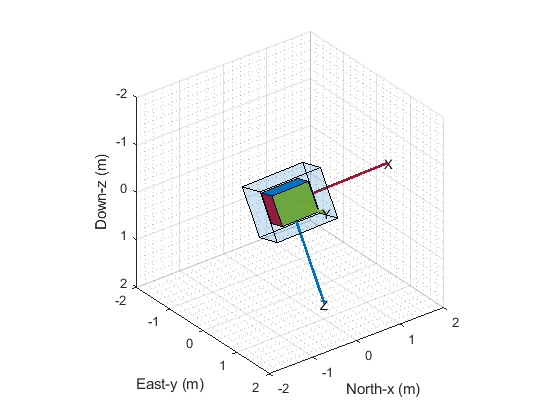

xlabel("North-x (m)")
ylabel("East-y (m)")
zlabel("Down-z (m)");

% Create orientation matrix
pos = [0 0 0];
for c = 1:391
    q = quaternion([OrientX(c) OrientY(c) OrientZ(c)], "eulerd", "XYZ", "frame");
    set(pp, Orientation = q, Position = pos);
    drawnow
end